## Live script demo of 'Optical Critical' example

% Add toolbox directories to MATLAB path
script_dir = fileparts(matlab.desktop.editor.getActiveFilename);

script_dir = '/home/mbexegc2/projects/mathworks/PPML---Periodically-Patterned-Multi-Layer/examples/live_scripts'

parts = strsplit(script_dir, filesep);
root_path = strjoin(parts(1:end-2), filesep);
all_dirs = split((genpath(root_path)), ':');
for i = 1:length(all_dirs)
    dir = all_dirs(i);
    if ~contains(dir, '.git')
        addpath(string(dir))
    end
end

Set stripe spacing (a) and etching depth (h)

% a is stripe spacing, aka lambda
a = 28;
% h is the etching depth
h = 4.7;

Angles of incidence

num_theta = 5;
start_theta = 13;
end_theta = 67;
theta = linspace(start_theta, end_theta, num_theta);  

Frequencies in THz

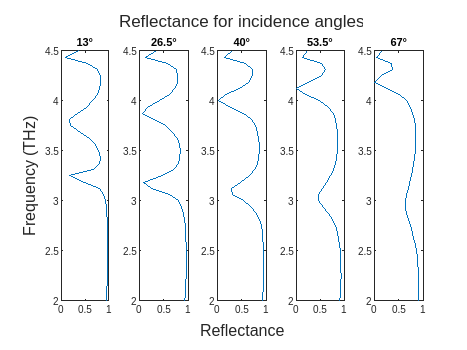

num_nu = 41;
start_nu = 2;
end_nu = 4.5;
nu = linspace(start_nu, end_nu, num_nu);      

 
optical_critical(a, h, theta, nu)